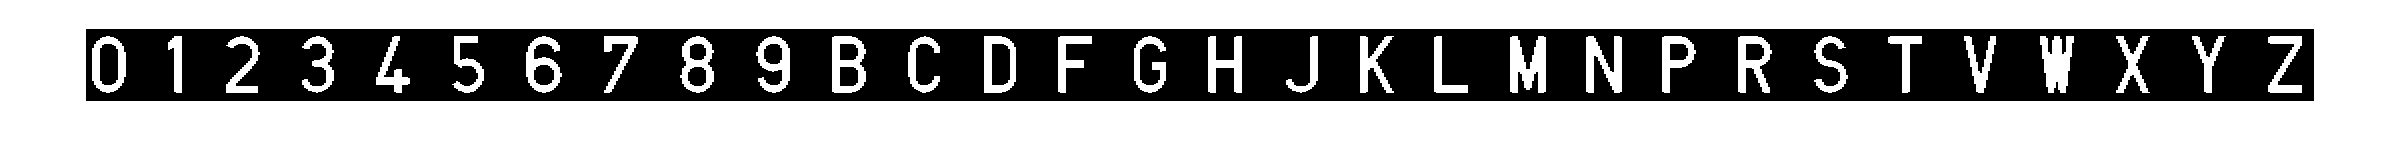

% Binarizacion
I = imread('Joc_de_caracters.jpg');
I = rgb2gray(I);
I = I < 40;
imshow(I)

% Separamos la imagen original entre las diferentes componentes connexas (caracteres).
CC = bwconncomp(I);

% Obtenemos imagenes binarias separadas de los caracteres
caracter = regionprops(CC, 'Image');

% Texto para las tablas
charnames = { '0'; '1'; '2'; '3'; '4'; '5'; '6'; '7'; '8'; ...
    '9'; 'B'; 'C'; 'D'; 'F'; 'G'; 'H'; 'J'; 'K'; 'L'; 'M'; ...
    'N'; 'P'; 'R'; 'S'; 'T'; 'V'; 'W'; 'X'; 'Y';'Z'};

% Calculo de los descriptores de Fourier para cada caracter.
FD_0 = FourierDescriptor(caracter(1).Image);
FD_1 = FourierDescriptor(caracter(2).Image);
FD_2 = FourierDescriptor(caracter(3).Image);
FD_3 = FourierDescriptor(caracter(4).Image);
FD_4 = FourierDescriptor(caracter(5).Image);
FD_5 = FourierDescriptor(caracter(6).Image);
FD_6 = FourierDescriptor(caracter(7).Image);
FD_7 = FourierDescriptor(caracter(8).Image);
FD_8 = FourierDescriptor(caracter(9).Image);
FD_9 = FourierDescriptor(caracter(10).Image);
FD_B = FourierDescriptor(caracter(11).Image);
FD_C = FourierDescriptor(caracter(12).Image);
FD_D = FourierDescriptor(caracter(13).Image);
FD_F = FourierDescriptor(caracter(14).Image);
FD_G = FourierDescriptor(caracter(15).Image);
FD_H = FourierDescriptor(caracter(16).Image);
FD_J = FourierDescriptor(caracter(17).Image);
FD_K = FourierDescriptor(caracter(18).Image);
FD_L = FourierDescriptor(caracter(19).Image);
FD_M = FourierDescriptor(caracter(20).Image);
FD_N = FourierDescriptor(caracter(21).Image);
FD_P = FourierDescriptor(caracter(22).Image);
FD_R = FourierDescriptor(caracter(23).Image);
FD_S = FourierDescriptor(caracter(24).Image);
FD_T = FourierDescriptor(caracter(25).Image);
FD_V = FourierDescriptor(caracter(26).Image);
FD_W = FourierDescriptor(caracter(27).Image);
FD_X = FourierDescriptor(caracter(28).Image);
FD_Y = FourierDescriptor(caracter(29).Image);
FD_Z = FourierDescriptor(caracter(30).Image);

fd_names = {'FD_0', 'FD_1', 'FD_2', 'FD_3', 'FD_4', 'FD_5', 'FD_6', ...
    'FD_7', 'FD_8', 'FD_9', 'FD_B', 'FD_C', 'FD_D', 'FD_F', 'FD_G', ...
    'FD_H', 'FD_J', 'FD_K', 'FD_L', 'FD_M', 'FD_N', 'FD_P', 'FD_R', ...
    'FD_S','FD_T', 'FD_V', 'FD_W', 'FD_X', 'FD_Y', 'FD_Z'};

T1 = table(FD_0,FD_1,FD_2,FD_3,FD_4,FD_5,FD_6,FD_7,FD_8,FD_9,FD_B, ...
FD_C,FD_D,FD_F,FD_G,FD_H,FD_J,FD_K,FD_L,FD_M,FD_N, FD_P,FD_R,FD_S, ...
FD_T,FD_V,FD_W,FD_X,FD_Y,FD_Z, 'VariableNames', fd_names')

T1 = 16×30 table
      FD_0         FD_1        FD_2        FD_3        FD_4        FD_5         FD_6        FD_7        FD_8        FD_9        FD_B        FD_C        FD_D         FD_F        FD_G        FD_H        FD_J        FD_K        FD_L         FD_M         FD_N        FD_P        FD_R        FD_S        FD_T        FD_V         FD_W         FD_X         FD_Y        FD_Z  
    _________    ________    ________    ____

% Separamos la imagen original entre las diferentes componentes connexas
CC = bwconncomp(I);



% Calculo de los descriptores basados en la excentricidad.
exc=regionprops(CC,'Eccentricity');
T2 = table([exc.Eccentricity]','RowNames', charnames, 'VariableNames', {'Eccentricity'})

T2 = 30×1 table
         Eccentricity
         ____________

    0      0.74434   
    1      0.98224   
    2      0.89516   
    3      0.87804   
    4      0.86239   
    5      0.88616   
    6       0.7733   
    7       0.8706   
    8      0.80146   
    9      0.79161   
    B      0.79089   
    C      0.85225   
    D      0.78676   
    F      0.89138   
    G       0.7903   
    H      0.57569   


% Calculo de los descriptores basados en la excentricidad.






